%{
%AER403 - Mechanism & Vibrations - W2021 - Final Project
%}
%%
close all
clear
clc


%Create Figure and all buttons/controls of the ui
mainfig = figure('Name','Simulation', 'NumberTitle','off'); 
%sim_b_velocity = uicontrol('Parent',mainfig,'Style','text','String','Point B Speed: 0','Units','normalized', 'Position',[0.01 0.21 .05 .03]);
%uicontrol('Parent',mainfig,'Style','text','String','Slider Velocity (mm/s):','Units','normalized', 'Position',[0.01 0.14 .05 .05]);
%sim_velocity = uicontrol('Parent',mainfig,'Style','edit','String',v_s,'Units','normalized', 'Position',[0.01 0.13 .05 .03]);
sim_start = uicontrol('Parent',mainfig,'Style','pushbutton','String','Start','Units','normalized', 'Position',[0.01 0.07 .05 .05], 'callback', 'sim_state = 1;');
sim_pause = uicontrol('Parent',mainfig,'Style','pushbutton','String','Pause','Units','normalized', 'Position',[0.01 0.01 .05 .05], 'callback', 'sim_state = 0;');

axis([-100 , 100, -100, 100]);


test = link([0, 0; 0, 10]);
test.set_input_joint(1,0);
test.set_input_function("rotation",0,[0,pi]);

test_connection = link([0,10; 10,10; 30,20]);

test.set_output_joints(2,test_connection);
test_connection.set_input_joint(1,test);

test_pivot = pivot_link([-10, -10], 25);

test_pivot_2 = pivot_link([-30, -30], 25);

test_leg = link([-30,-30; 10,10; 30,30]);
test_leg.set_input_joint(1,test_connection);

test_connection.set_pivot_links(2,test_pivot);

test_connection.set_output_joints(3,test_leg);

test_leg.set_pivot_links(2,test_pivot_2);

test_leg.set_output_joints(3,0)

ans =   link with properties:

     number_of_joints: 3
         joint_points: [3×2 double]
        anchor_joints: []
         input_joints: 1
           input_link: [1×1 link]
         pivot_joints: 2
          pivot_links: [1×1 pivot_link]
        output_joints: 3
         output_links: 0
     old_output_point: [0 0]
           input_type: 0
         input_limits: 0
    current_direction: []


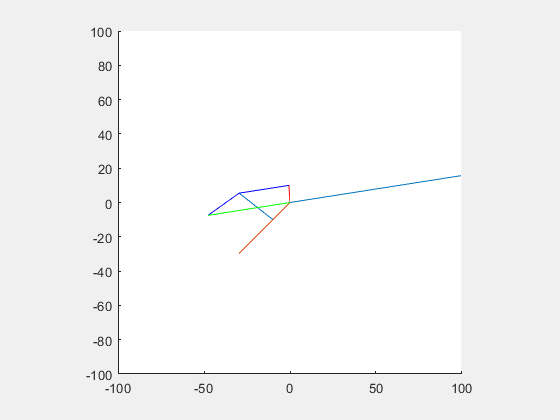

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

Intersection Error

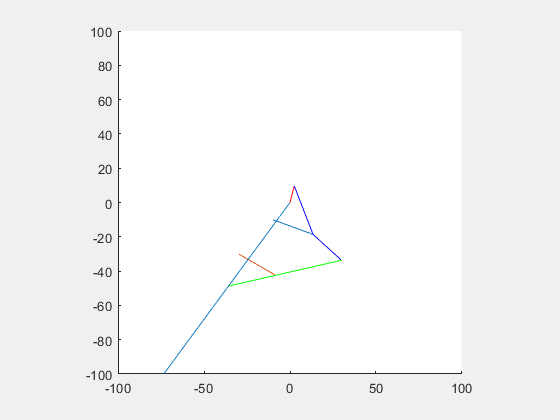



for i = 1:1000
    
    clf()
    axis([-100 , 100, -100, 100]);
    test_pivot.update_point(test.joint_points(2,:), 30, 0);
    test_pivot_2.update_point(test_leg.joint_points(1,:),20, 0);
    axis square;
    subplot(1,1,1)
    test.update_now(1,100, 0)
    test_connection.update_now(1,100,0)
    test_leg.update_now(1,100,0)
    
    hold on
    test_pivot.draw_now();
    test_pivot_2.draw_now();
    test.draw_now('red')
    test_connection.draw_now('blue');
    test_leg.draw_now('green');
    %plot(nsidedpoly(1000, 'Center', [-30 -10], 'Radius', 25))
    %plot(nsidedpoly(1000, 'Center', test.joint_points(2,:), 'Radius', 30))
    hold off
    
    pause(.05)
    
end